# Ejemplo Practico: Calificaciones de Estudiantes

Utilizando vectores de estructuras con funciones.

Se desea calcular y mostrar el promedio de cada uno de los estudiantes.

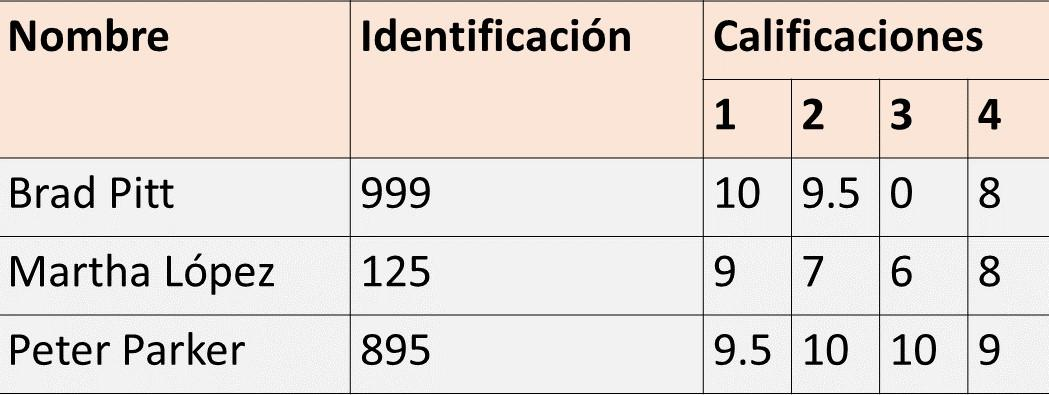

Crear una funcion que haga lo siguiente:

- Imprimir el titulo de las columnas [Nombre, Promedio]

- Recorrer cada estudiante del vector de estructuras.

               Sumar las notas

               Calcular el promedio

               mostrar el promedio

## Crear el vector de Estructuras

estudiantes(1) = struct('nombre','Brad Pitt','identificacion',999,'calificaciones',[10 9.5 0 8])

estudiantes = 1×3 struct array with fields:
    nombre
    identificacion
    calificaciones


estudiantes(2) = struct('nombre','Martha Lopez','identificacion',125,'calificaciones',[9 7 6 8])

estudiantes = 1×3 struct array with fields:
    nombre
    identificacion
    calificaciones


estudiantes(3) = struct('nombre','Peter Parker','identificacion',895,'calificaciones',[9.5 10 10 9])

estudiantes = 1×3 struct array with fields:
    nombre
    identificacion
    calificaciones


## Llamar la funcion

mostrarPromedios(estudiantes)

Nombre               Promedio  
Brad Pitt            6.875000e+00
Martha Lopez         7.500000e+00
Peter Parker         9.625000e+00


## Crear la funcion

function mostrarPromedios(estudiantes)
    fprintf('%-20s %-10s\n','Nombre','Promedio');
    for i = 1:length(estudiantes)
        sumaNotas = sum([estudiantes(i).calificaciones]);
        cantidadNotas = length([estudiantes(i).calificaciones]);
        promedio = sumaNotas/cantidadNotas;

        fprintf('%-20s %-10s\n',estudiantes(i).nombre,promedio);
    end
end